# Image Filtering

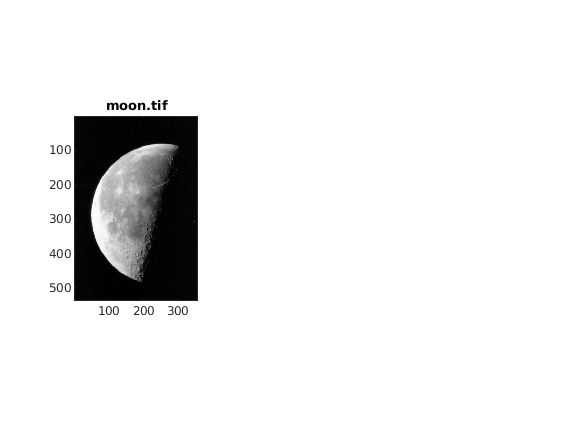

img = imread("moon.tif");
subplot(1,3,1);
image(img);
colormap('gray');
title('moon.tif');
axis tight equal;

## Gaussian Filter

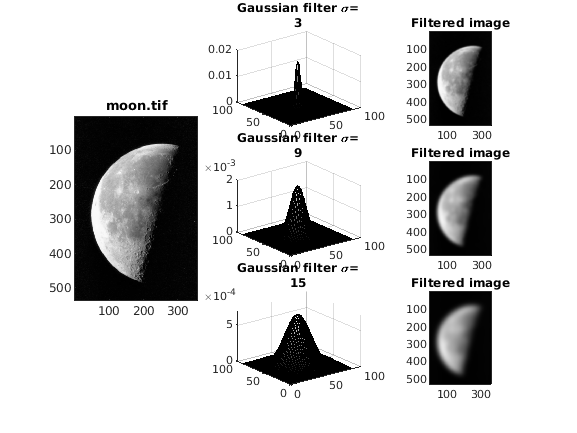

sigma = 3;
filt = fspecial('gaussian',[90,90],sigma);
subplot(3,3,2);
surf(filt);
title(["Gaussian filter \sigma=",num2str(sigma)]);
img_filt = conv2(img,filt,'same');
subplot(3,3,3);
image(img_filt);
title("Filtered image");
axis tight equal;
sigma = 9;
filt = fspecial('gaussian',[90,90],sigma);
subplot(3,3,5);
surf(filt);
title(["Gaussian filter \sigma=",num2str(sigma)]);
img_filt = conv2(img,filt,'same');
subplot(3,3,6);
image(img_filt);
title("Filtered image");
axis tight equal;
sigma = 15;
filt = fspecial('gaussian',[90,90],sigma);
subplot(3,3,8);
surf(filt);
title(["Gaussian filter \sigma=",num2str(sigma)]);
img_filt = conv2(img,filt,'same');
subplot(3,3,9);
image(img_filt);
title("Filtered image");
axis tight equal;

## Filtering Noise(Gaussian Filter - low-pass)

For noise that is independent across pixels such as static type white noise. 

Often very small values of Sigma work well.

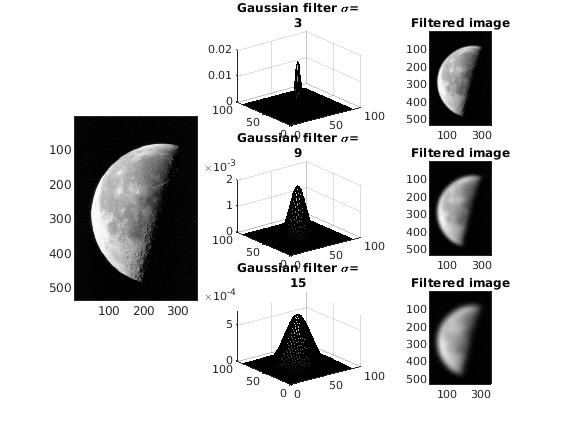

figure(2);
subplot(1,3,1);
image(img);
axis tight equal;
colormap('gray');

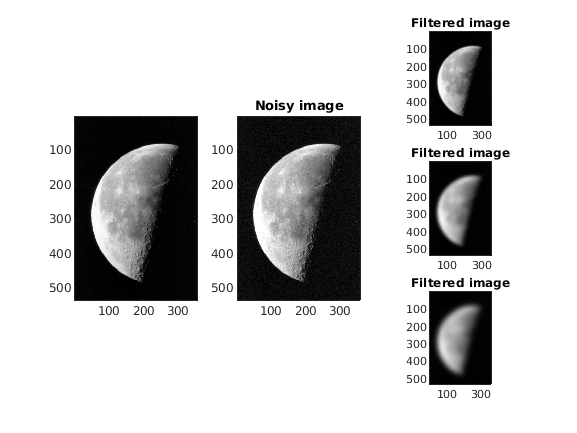

rng(0);
img_noise = double(img)+20*rand(size(img));
subplot(1,3,2);
image(img_noise);
title('Noisy image');
axis tight equal;

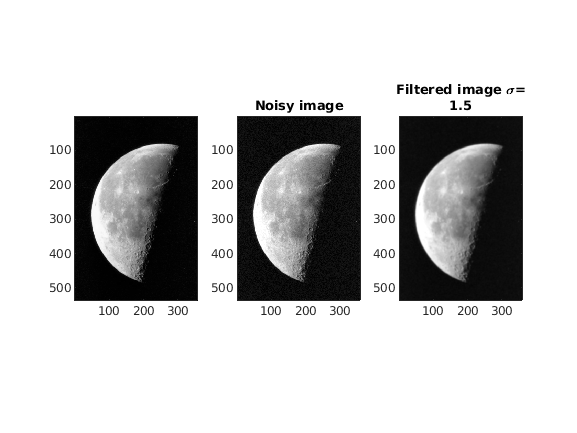

sigma = 1.5;
W = 6*sigma;
filt = fspecial('gaussian',[W,W],sigma);
img_filt = conv2(img_noise,filt,'same');
subplot(1,3,3);
image(img_filt);
title(['Filtered image \sigma=',sprintf("%.1f",sigma)]);
axis tight equal;

## Sharpening Images(High-pass filter)

High pass filters are useful for sharpening images,

They're also useful for edge detection for object segmentation images, 

### Sobel Filter

filt_sobelh = fspecial('sobel');%Returns horizontal sobel filter
filt_sobelv = filt_sobelh';%Vertical Sobel filter
figure(3);
colormap('gray');

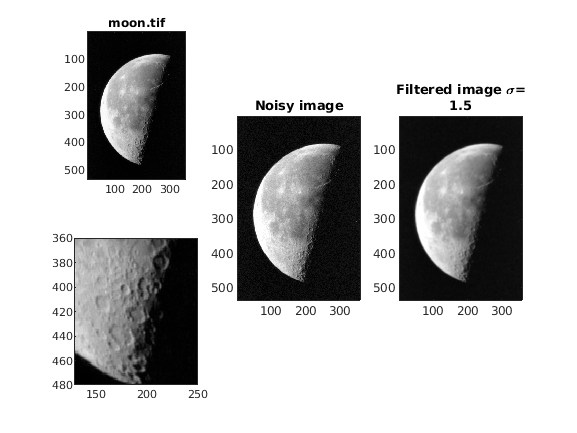

subplot(2,3,1);
image(img);
title('moon.tif');
axis tight equal;
subplot(2,3,4);
image(img);
axis([130,250,360,480]);

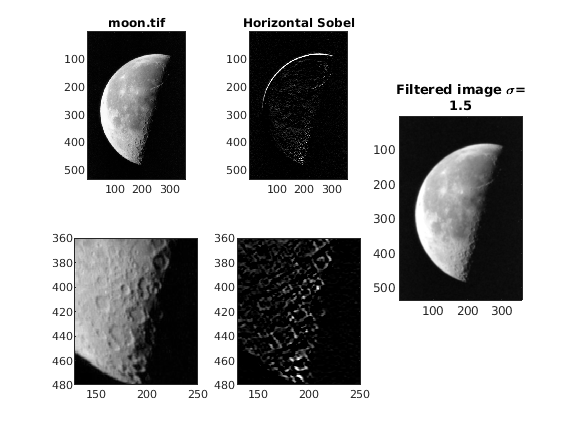

img_sobelh = conv2(img, filt_sobelh, 'same');
subplot(2,3,2);
image(img_sobelh);
axis tight equal;
title('Horizontal Sobel');
subplot(2,3,5);
image(img_sobelh);
axis([130,250,360,480]);

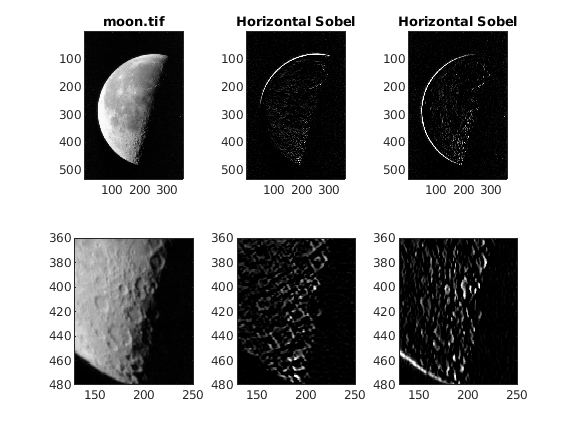

img_sobelv = conv2(img, filt_sobelv, 'same');
subplot(2,3,3);
image(img_sobelv);
axis tight equal;
title('Horizontal Sobel');
subplot(2,3,6);
image(img_sobelv);
axis([130,250,360,480]);

## Laplacian of Gaussian filter(Edge detection)

Laplacian Operator Computes what is called the divergents of the gradient of 

the image intensities.

The derivative and the rows direction from a horizontal Sobel filter, 

along with the derivative in the columns direction from a vertical Sobel 

filter form a two dimensional gradient.

At every pixel with us, describe a gradient vector for 

that pixel with two numbers. 

The Rows intensity derivative and the columns intensity derivative.

We can display these gradient vectors using the quiver function.

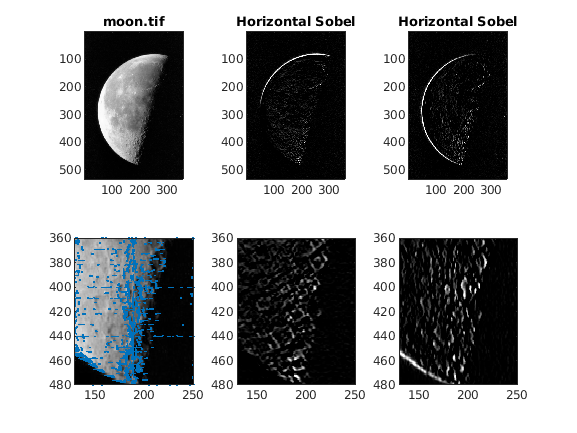

subplot(2,3,4);
hold on;
quiver(img_sobelv,img_sobelh,'LineWidth',2);
hold off;

### Gaussian part

it turns out that due to fun math tricks convolving the derivative or second derivative, or in general nth order derivative of a signal with a Gaussian is exactly the same as convolving the signal itself with the same order derivative of a Gaussian. So instead of needing to compute the Laplacian of the image, 

we do it to the Gaussian filter. Giving us the Laplacian of Gaussian filter that when we convolve it with 

the image both reduces noise and computes the Laplacian.

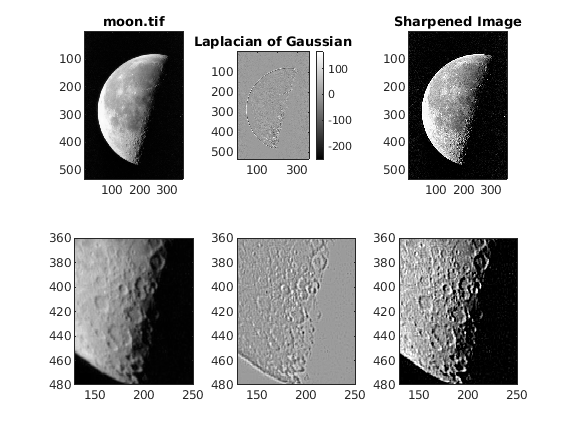

filt_log = fspecial('log');%Log = Laplacian of Gaussian
img_log = conv2(img,filt_log,'same');
subplot(2,3,2);
imagesc(img_log);
title("Laplacian of Gaussian");
colorbar;
axis tight equal;
subplot(2,3,5);
imagesc(img_log);
axis([130,250,360,480]);
%Sharpening using LoG
img_sharp = double(img) - 1*img_log;
subplot(2,3,4);
image(img);
axis([130,250,360,480]);
subplot(2,3,3);
image(img_sharp);
axis tight equal;
title("Sharpened Image");
subplot(2,3,6);
image(img_sharp);
axis([130,250,360,480]);

## Median Filter

Non-convolution based filter

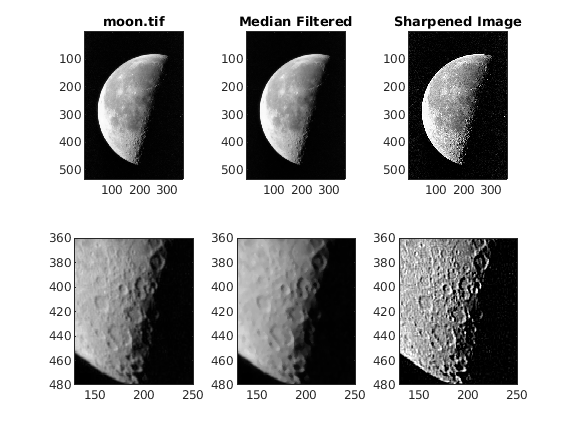

img_med = img;
for i=2:size(img,1)-1
    for j=2:size(img,2)-1
        img_med(i,j)=median(img(i-1:i+1,j-1:j+1),'all');
    end
end
subplot(2,3,1);
image(img);
axis tight equal;
title('moon.tif');
subplot(2,3,4);
image(img);
axis([130,250,360,480]);
subplot(2,3,2);
image(img_med);
axis tight equal;
title('Median Filtered');
subplot(2,3,5);
image(img_med);
axis([130,250,360,480]);

# Matching Filter

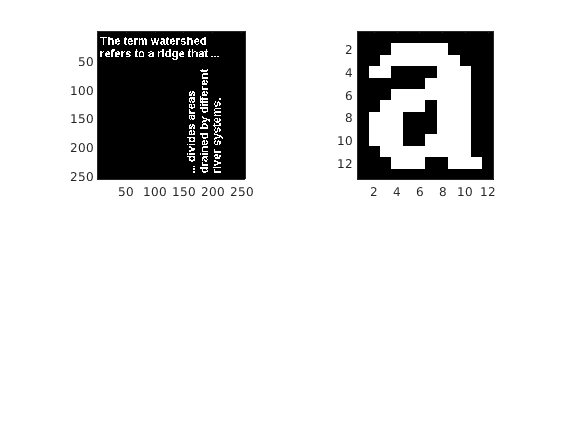

img = imread('text.png');
figure(4);
subplot(2,2,1);
imagesc(img);
axis tight equal;
subplot(2,2,2);
match = img(33:45,88:99);
imagesc(match);
axis tight equal;

## Add Random Noise to Original image

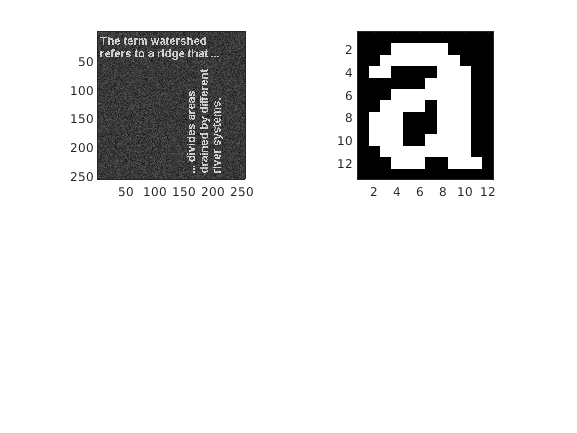

rng(0);
img = img + 0.05*randn(size(img));
subplot(2,2,1);
imagesc(img);
axis tight equal;

## Matching the Filter to Image using Pearson's Coefficient Function

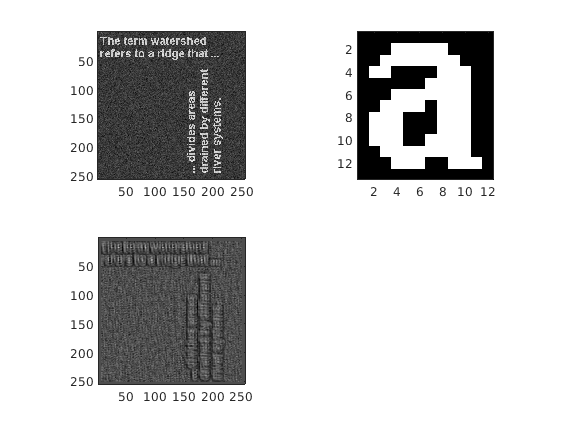

img_match = zeros(size(img));
[r,c] = size(match);
dr = floor(r/2);
dc = floor(c/2);
for i=1:size(img,1)-r+1
    for j=1:size(img,2)-c+1
        img_match(i+dr,j+dc) = corr(match(:),reshape(img(i:i+r-1,j:j+c-1),[r*c,1]));
    end
end
subplot(2,2,3);
imagesc(img_match);
axis tight equal;

## Box the match

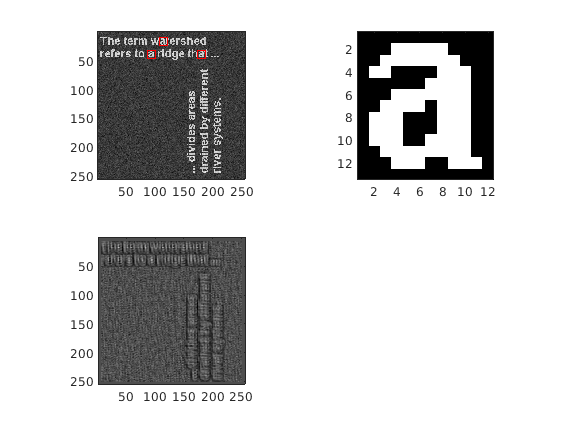

[boxr, boxc] = find(img_match>0.6);
subplot(2,2,1);
DrawBoxes(boxr,boxc);
%Higher matching treshold
subplot(2,2,1);
imagesc(img);
axis tight equal;
[boxr, boxc] = find(img_match>0.75);
subplot(2,2,1);
DrawBoxes(boxr,boxc);

## Different Filter Orientation

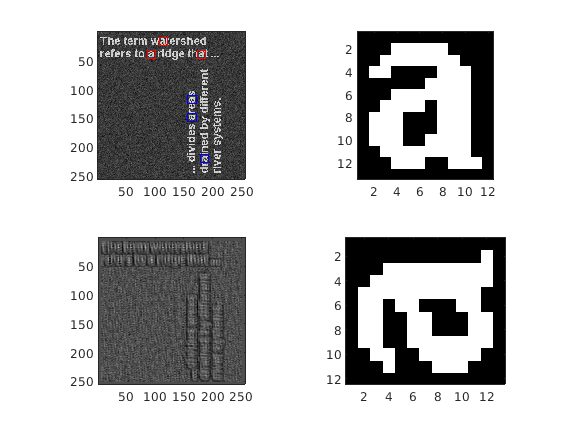

match2 = flipud(match');
subplot(2,2,4);
imagesc(match2);
axis tight equal;
img_match2 = zeros(size(img));
[r,c] = size(match2);
for i=1:size(img,1)-r+1
    for j=1:size(img,2)-c+1
        img_match2(i+dr,j+dc) = corr(match2(:),reshape(img(i:i+r-1,j:j+c-1),[r*c,1]));
    end
end
[boxr, boxc] = find(img_match2>0.75);
subplot(2,2,1);
DrawBoxes(boxr,boxc,'b');

# Motion Filter

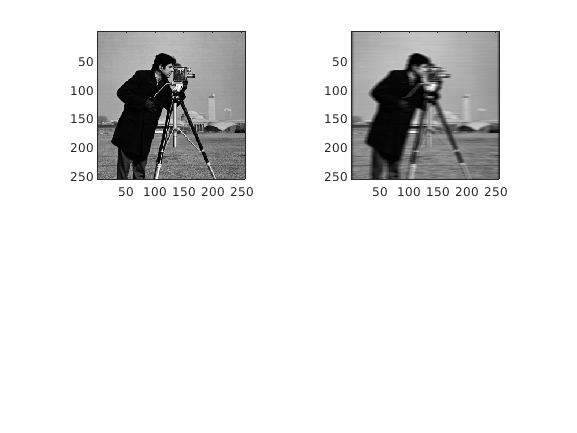

img = imread('cameraman.tif');
filt = fspecial('motion');
figure(5);
colormap('gray');
subplot(2,2,1);
imagesc(img);
axis tight equal;
img_motion = conv2(img,filt,'same');
subplot(2,2,2);
imagesc(img_motion);
axis tight equal;